# TD3

## 1.1 shannon定理

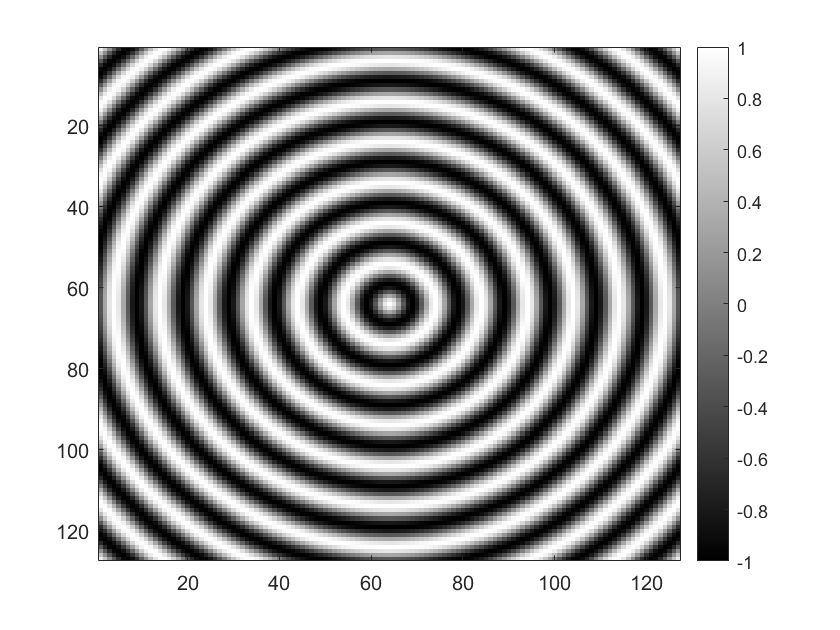

%grille de discretisation
C=127;
%L'effet de moiré (dû au recouvrement commence à être visible pour R=2)
R=10;%recouvrement pour R<=2

x=-floor((C+1)/2)+1:floor((C+1)/2)-1; %floor功能是向下取整
X=repmat(x,C,1);
Y=X';
%image sinusoidale
Im=cos(2*pi*sqrt(X.^2+Y.^2)/R);%sinusoide de frequence saptiale 1/R
figure;imagesc(Im);colormap("gray");colorbar

## 1.2spectre

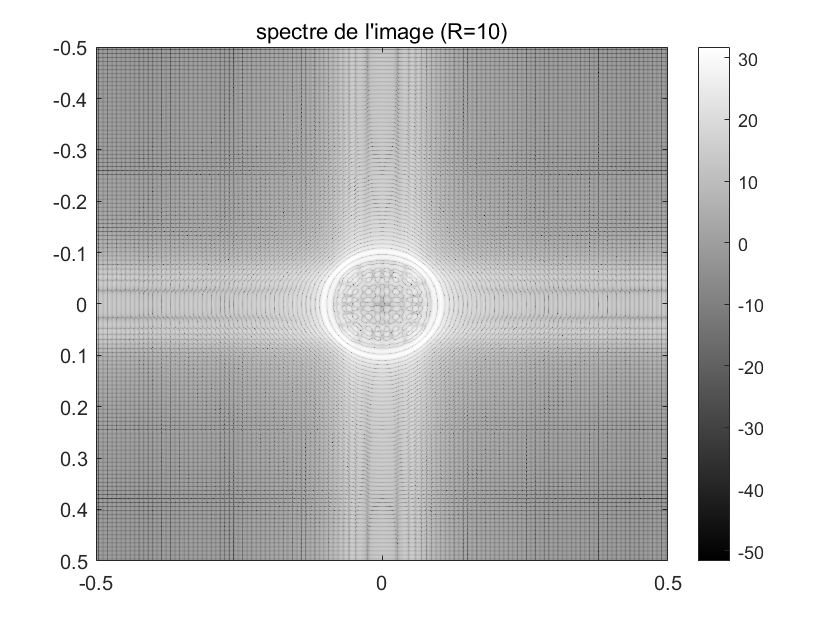

%Spectre
%----------------
%mean=0，所有spectre没有中间点
%TF: N*N points dans TF, 增加点
FI=(fft2(Im,1024,1024));%zero padding, plus de points sur spectre
figure;imagesc([-.5,.5],[-.5,.5],10*log10(abs(fftshift(FI))));colormap("gray");colorbar;title("spectre de l'image (R=10)")

%L’image est une sinusoïde de fréquence spatiale réduite isotrope =1/R (=>spectre = cercle de rayon 1/R)
%有圆圈外的两棒spectre：因为是discret的表示为sinc(),Elles sont dues au fait que l image est de support spatial fini (troncature d une sinusoïde de support infini par une fenêtre rectangle 2D). Le spectre obtenu résulte de la convolution2D d une impulsion de Dirac par : sin(N pi nu1)/sin(pi nu1)x sin(N pi nu2)/sin(pi nu2)
%解决办法：Atténuer l effet en pondérant l’image par une fenêtre de Hann 2D dont le spectre décroit plus vite avec la fréquence que la fenêtre rectangulaire.

## 2.1傅里叶分析

En affichant en échelle linéaire on ne verra que la valeur de la TF en zéro =

valeur moyenne de l’image. En effet les autres composantes fréquentielles

(correspondant aux variations d’intensité, qui sont faibles comparées à la

moyenne) sont d’amplitude très faible par rapport à la valeur en 0. D’où

l’intérêt d’une échelle log pour les mettre en évidence lorsque l’image est de

valeur moyenne non nulle.

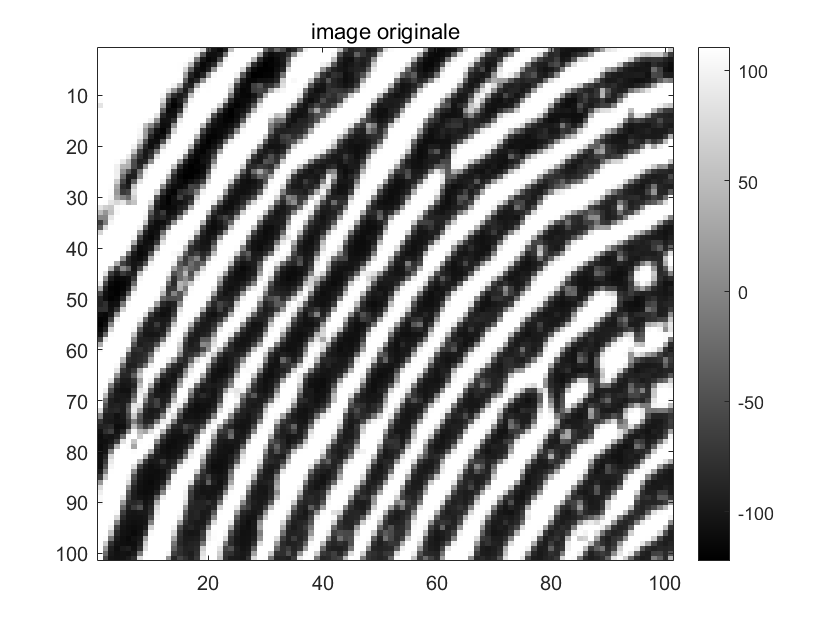

close all
load empreinte
image =I(50:150,100:200);
image=double(image);
image=image-mean(image(:));%让mean变为0，便于观察
taille=size(image);
figure;imagesc(image);title("image originale");colormap("gray");colorbar

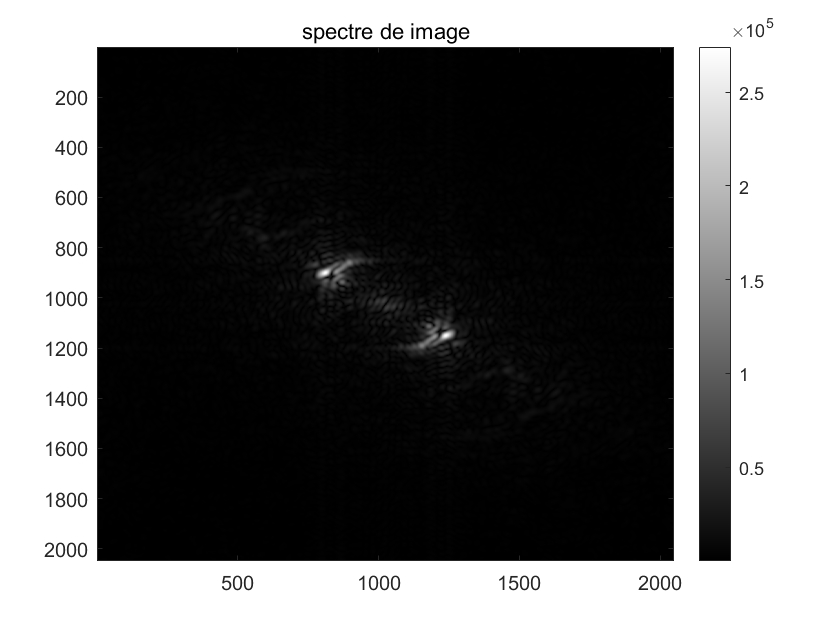


%caracterisation spectrale
%-----------------------
%spectre avec azero padding pour augmenter le nb de points de spectre
N=2048; %一般取原来的10倍
TFim=fft2(image,N,N);
figure;imagesc(fftshift(abs(TFim)));title("spectre de image");colormap(gray);colorbar

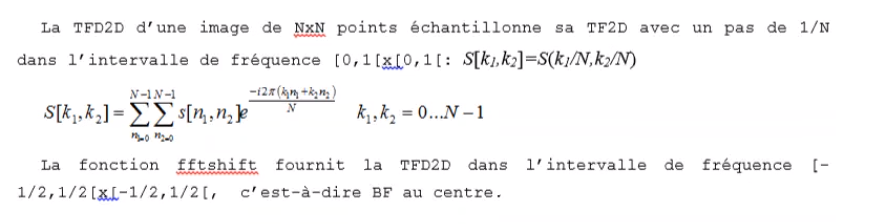

## 2.2主要空间频率估计

% fréquence prépondérante
[val,indj]=max(max(abs(TFim(1:N/2,1:N/2))))

val = 2.7400e+05

indj = 215

[val,indi]=max(max(abs(TFim(1:N/2,1:N/2))'))

val = 2.7400e+05

indi = 126

% module
nu=sqrt(((indi-1)/N)^2+((indj-1)/N)^2);
disp(['nu :',num2str(nu)]);

nu :0.12101


% orientation
theta=atan((indi-1)/(indj-1))*180/pi;
disp(['theta :',num2str(theta)]);

theta :30.2897


## 3.1 线性滤波

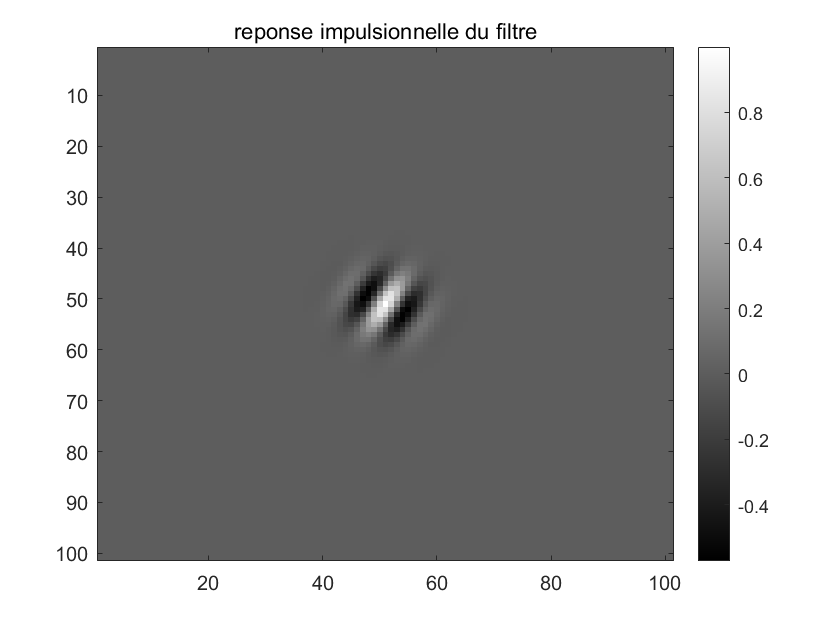

% filtre gaussien passe-bande
%-----------------------------
%parametres
f=nu;%1/10;
dx=4;
dy=4;
% grille de discretisation
[L,C]=size(image);
x=-floor((C+1)/2)+1:floor((C+1)/2)-1;
X = repmat(x,L, 1);
y=-floor((L+1)/2)+1:floor((L+1)/2)-1;
Y= repmat(y',1,C);
% rep impulsionnelle
H=exp(-(1/2)*((X.^2)/dx^2+(Y.^2)/dy^2)).*cos(2*pi*f*X); %sinusoide modulee en amplitude
Ht=imrotate(H,-theta,'bilinear','crop'); %rotation
figure ;
imagesc(Ht);title(' reponse impulsionnelle du filtre ');colormap(gray);colorbar

## 3.2在频域滤波

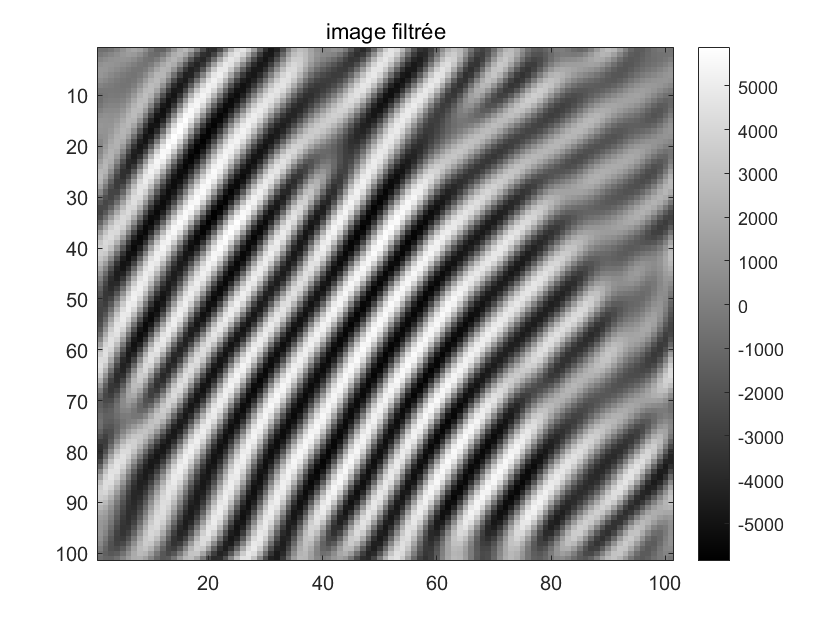

% filtrage
%-----------
FI=fft2(image);
Fh=fft2(Ht);
FG=FI.*Fh;
IG=fftshift(ifft2(FG));
figure;imagesc(IG); title('image filtrée');colormap(gray);colorbar

disp("Les « imperfections »  de l'image empreinte sont éliminées par filtrage.")

Les « imperfections »  de l'image empreinte sont éliminées par filtrage.


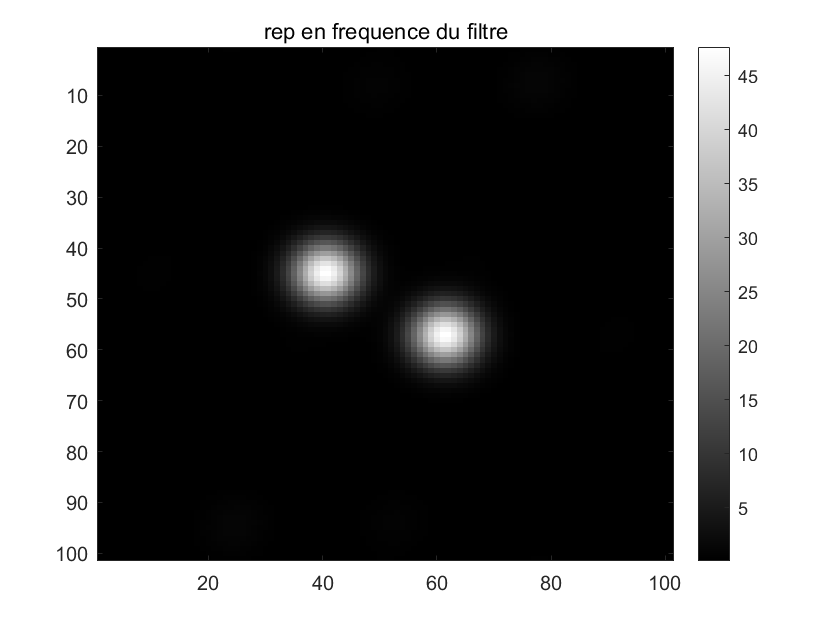

figure;imagesc(((abs(fftshift(Fh)))));
title('rep en frequence du filtre');colormap(gray);colorbar